**Grupo 8: Ana Robledano Abasolo, Alfredo Robledano Abasolo, **

**Melani Tatayo Culchas, Rubén Sierra Serrano**

Fecha: 06/05/2023

# **Ejercicio 1**

## Problema T6_7.1. Primera y segunda derivadas en puntos no equiespaciados

clear, clc % Limpieza del entorno de trabajo

a) Escribir una función en Matlab que calcule la primera y segunda derivada de una función que viene dada por un conjunto de puntos discretos desigualmente espaciados.

- Véase PyDerDes.m

b) Utiliza la función creada para resolver el siguiente problema. En la siguiente tabla se da la posición $\left(x,y\right)$ de los coches de una montaña rusa en función del tiempo $t$.

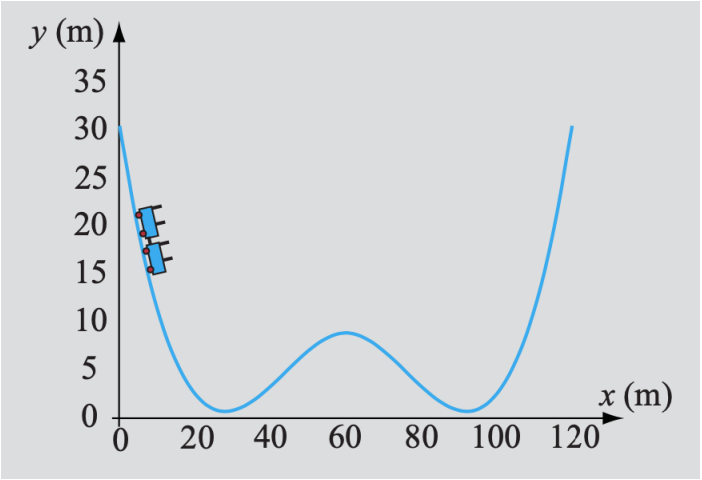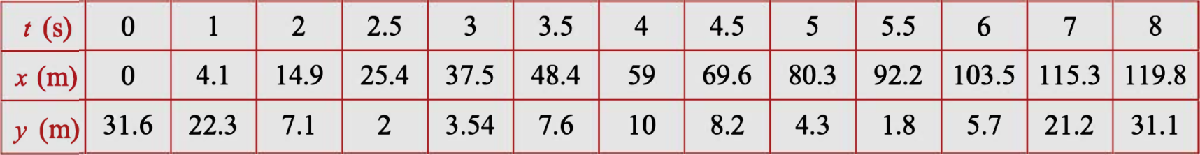

t = [0, 1, 2, 2.5, 3, 3.5, 4, 4.5, 5, 5.5, 6, 7, 8];
x = [0, 4.1, 14.9, 25.4, 37.5, 48.4, 59, 69.6, 80.3, 92.2, 103.5, 115.3, 119.8];
y = [31.6, 22.3, 7.1, 2, 3.54, 7.6, 10, 8.2, 4.3, 1.8, 5.7, 21.2, 31.1];

La velocidad está dada por: 


$$v=\sqrt{{v_x }^2 +{v_y }^2 }$$
            
$$v_x =\frac{\textrm{dx}}{\textrm{dt}}$$
            
$$v_y =\frac{\textrm{dy}}{\textrm{dt}}$$


La acelaración está dada por:


$$a=\sqrt{{a_x }^2 +{a_y }^2 }$$
            
$$a_x =\frac{d^2 x}{\textrm{dt}}$$
            
$$a_y =\frac{d^2 y}{\textrm{dt}}$$


b.1) Calcula la velocidad y la aceleración para cada instante t. Da el resultado en una tabla donde las columnas sean: t(s), x(m), y(m), v(m/s), a(m/s²)

Usando PySDerDes obtenemos los valores de la velocidad y aceleración en los puntos dato

[xd, xdd] = PySDerDes(t, x);
[yd, ydd] = PySDerDes(t, y);
v = sqrt(xd.^2+yd.^2);
a = sqrt(xdd.^2+ydd.^2);

Guardamos en una tabla los resultados obtenidos

res = table( ...
    num2str(t', '%.2f'), ...
    num2str(x', '%.2f'), ...
    num2str(y', '%.2f'),...
    num2str(v', '%.4f'), ...
    num2str(a', '%.4f'), ...
    VariableNames={'t(s)', 'x(m)', 'y(m)', 'v(m/s)', 'a(m/s²)'});
disp(res)

    t(s)     x(m)     y(m)      v(m/s)     a(m/s²) 
    ____    ______    _____    ________    ________

    0.00      0.00    31.60      8.4537     26.5391
    1.00      4.10    22.30     15.5520     15.5520
    2.00     14.90     7.10      7.9961      7.9961
    2.50     25.40     2.00     45.8017     45.8017
    3.00     37.50     3.54     66.8000     66.8000
    3.50     48.40     7.60     80.7716     80.7716
    4.00     59.00    10.00    101.5074    101.5074
    4.50     69.60     8.20    101.8945    101.8945
    5.00     80.30     4.30     95.0303     95.0303
    5.50     92.20     1.80    138.9539    138.9539
    6.00    103.50     5.70    146.2935    146.2935
    7.00    115.30    21.20    127.5982    165.1292
    8.00    119.80    31.10    135.7568    198.6945



b.2) Dibuja (tres gráficas en la misma página) las gráficas de $y=f\left(x\right)$    $v=v\left(t\right)$    $a=a\left(t\right)$

Límites de las gráficas

l1_x = min(x); l2_x = max(x);
xx = linspace(l1_x, l2_x);
l1_t = min(t); l2_t = max(t);
tt = linspace(l1_t, l2_t);

Realizamos 3 subplots para tener las gráficas en la misma página

Subplot de posición (x, y)

subplot(3, 1, 1)
plot(x, y,'b.', MarkerSize=12);
pp = spline(x, y);
yy = ppval(pp, xx);
hold on
plot(xx, yy, 'b-')
title('Posición m')
xlabel('x'); ylabel('y(x)')
hold off

Subplot de velocidad v(t)

subplot(3, 1, 2)
plot(t, v, 'r.', MarkerSize=12)
pp = spline(t, v);
yy = ppval(pp, tt);
hold on
plot(tt, yy, 'r-')
title('Velocidad m/s')
xlabel('t'); ylabel('v(t)')
hold off

Subplot de aceleración a(t)

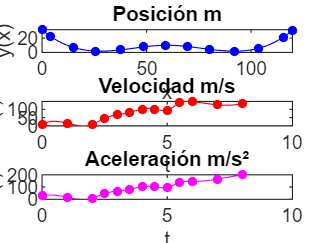

subplot(3, 1, 3)
plot(t, a, 'm.', MarkerSize=12)
pp = spline(t, a);
yy = ppval(pp, tt);
hold on
plot(tt, yy, 'm-')
title('Aceleración m/s²')
xlabel('t'); ylabel('a(t)')
hold off

# **Ejercicio 3**

## Problema T6_7.3. Extrapolación de Richardson

clear, clc % Limpieza del entorno de trabajo

a) Crea una función en Matlab para calcular la primera y segunda derivadas de una función dada en forma anónima en un punto 𝑥. mediante extrapolación de Richardson con diferencias centrales de dos puntos para la primera derivada y de tres puntos para la segunda.

- Véase DerRichardson.m

b) Emplea la función anterior para calcular la primera y segunda derivadas de la función $f\left(x\right)={\textrm{xe}}^x$ en el punto $x=2$ comenzando con $\textrm{hin}=0\ldotp 4$ y $N=4$. Calcula el error relativo porcentual calculando analíticamente las derivadas y sustituyendo. Da los resultados en una tabla en la que aparezcan los valores de cada derivada calculados mediante Matlab y con el algoritmo de Richardson y el valor absoluto de su diferencia.

Zona de declaración de variables

fun = @(x) x*exp(x);
x0 = 2;
hin = 0.4;
N = 4;

Cálculo de las derivadas con DerRichardson

[dfdx, d2fdx] = DerRichardson(fun, x0, hin, N)

Los resultados para orden de extrapolación N son los últimos valores de la matrices dfdx y d2fdx

h = dfdx(end, 1);
dfdx = dfdx(end, end);
fprintf("La 1ª derivada obtenida con Richardson es:\n%.4f", dfdx)
d2fdx = d2fdx(end, end);
fprintf("La 2ª derivada obtenida con Richardson es:\n%.4f", d2fdx)

Se calculan las derivadas analíticas con MatLab

syms x
dfdx_matlab = diff(fun(x), x);
d2fdx_matlab = diff(fun(x), x, 2);
dfdx_matlab = double(subs(dfdx_matlab, x, x0));
fprintf("La 1ª derivada obtenida con MatLab es:\n%.4f", dfdx_matlab)
d2fdx_matlab = double(subs(d2fdx_matlab, x, x0));
fprintf("La 2ª derivada obtenida con MatLab es:\n%.4f", d2fdx_matlab)

Error relativo porcentual entre las derivadas calculadas por MatLab y por Richardson

error_relativo_dfdx = abs(dfdx-dfdx_matlab)/abs(dfdx)*100;
error_relativo_d2fdx = abs(d2fdx-d2fdx_matlab)/abs(d2fdx)*100;
fprintf("Error relativo porcentual en la 1ª derivada:\n%e %%", error_relativo_dfdx)
fprintf("Error relativo porcentual en la 2ª derivada:\n%e %%", error_relativo_d2fdx)

Se calculan las diferencias absolutas entre el resultado de MatLab y el obtenido por Richardson

abs_difdf = abs(dfdx_matlab-dfdx);
abs_difd2f = abs(d2fdx_matlab-d2fdx);

Se guardan en una tabla los resultados

T = table(h, dfdx, dfdx_matlab, abs_difdf, d2fdx, d2fdx_matlab, abs_difd2f);
T.Properties.VariableNames = ["h", ...
    "1ªDer_Richardson", "1ªDer_MatLab", "AbsDif_1ªDer", ...
    "2ªDer_Richardson", "2ªDer_MatLab", "AbsDif_2ªDer"];

Finalmente se muestra la tabla

disp('Resultados:')
disp(T)